# Week 8: Sparse matrices in MATLAB

## 1 "sparse" and "full" 

In MATLAB, the standard (non-sparse) format is called "**full**".

To convert between sparse and full formats, use the `sparse()` and `full()` functions.

clear;
A = [1.0,   0,    0, -2.0,  0;
       0, 2.5, -1.0,    0,  0;
    -0.5,   0,    0,   12, -6;
       0,   0,    0,  1.0, 0;
       0,  -3,    0     0  0]

A =     1.0000         0         0   -2.0000         0
         0    2.5000   -1.0000         0         0
   -0.5000         0         0   12.0000   -6.0000
         0         0         0    1.0000         0
         0   -3.0000         0         0         0


B = sparse(A)

B =    (1,1)       1.0000
   (3,1)      -0.5000
   (2,2)       2.5000
   (5,2)      -3.0000
   (2,3)      -1.0000
   (1,4)      -2.0000
   (3,4)      12.0000
   (4,4)       1.0000
   (3,5)      -6.0000


Note the triplet format that is used to express the output of B: 

Also notice the order in which elements are stored: first the entries in Column 1, then Column 2, etc. And indices are always increasing.

To convert from sparse to full, use the `full()` function.

C = full(B)

C =     1.0000         0         0   -2.0000         0
         0    2.5000   -1.0000         0         0
   -0.5000         0         0   12.0000   -6.0000
         0         0         0    1.0000         0
         0   -3.0000         0         0         0


isequal(A,C)

ans = logical
   1


However, it is rarely a good idea to build a sparse matrix by first constucting a "full" one, and then converting to sparse. 

Two other functions that are very useful when dealing with sparse matrices: 

- `spy() `visualises the spacity pattern

- `nnz() `reports the number of non-zeros.

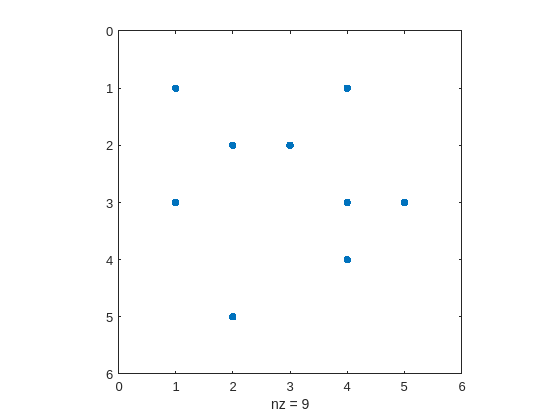

spy(B)

nnz(B)

ans = 9

## 2. Storage

We should be able to verify that storing a matrix in sparse format can save space. The number of bytes required is given by the "`whos()`" function

whos A B

  Name      Size            Bytes  Class     Attributes

  A         5x5               200  double              
  B         5x5               192  double    sparse    



Let's try to larger matrices to see if there is much of a saving. This one is deliberately not a good candidate for a sparse matrix: all the entries are 1.

N = 10;
A2 = ones(N);
B2 = sparse(A2);
whos A2 B2

  Name       Size            Bytes  Class     Attributes

  A2        10x10              800  double              
  B2        10x10             1688  double    sparse    



This shows that if the matrix is "dense", we should not use sparse format. 

Here,  "density" refers to the proportion of non-zeros in a matrix: it is `d=nnz(A)/numel(A)`:

fprintf("The density of A is d=%f", nnz(A)/numel(A))

The density of A is d=0.360000

fprintf("The density of A2 (the matrix of 1s) is d=%f", nnz(A2)/numel(A2))

The density of A2 (the matrix of 1s) is d=1.000000

This leads to two questions:

-  can we predict how much memory is required to store a sparse matrix?

- for what value of $d$ to we save memory by storing a  matrix as sparse?

To answer Q1: Although MATLAB presents a sparse matrix in triplet form, it actually uses Compressed Column. Also, it uses 8 bytes for both indicies and values. So an $N \times N$ matrix will need $2 \times 8 \times NNZ + 8(N+1)$ bytes:

whos B

  Name      Size            Bytes  Class     Attributes

  B         5x5               192  double    sparse    



2*8*nnz(B) + 8*(length(B)+1)

ans = 192

## 3. Building sparse matrices.

 There are several functions that automatically return sparse matrices, including

- `speye(N)` : sparse $N \times N$ identity matrix

- `sprand(m,n,d): a random `$m \times n$ matrix with specified denesity, $d$. 

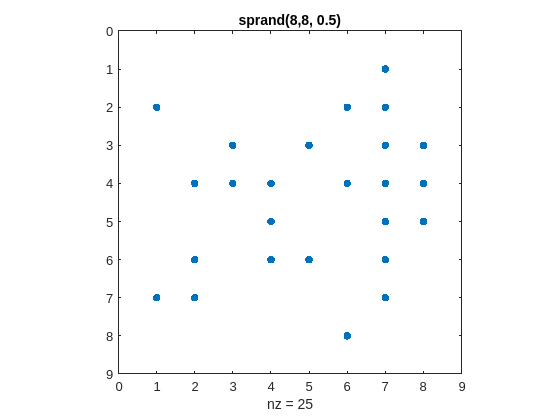

A3 = sprand(8,8, 0.5); 
spy(A3); title('sprand(8,8, 0.5)')

However, usually we construct matrices in a more deterministic way.

One way to do this  is to make an empty sparse matrix. Then, when we add elements to it, it stays sparse. 

In the following example, we'll make a tridiagonal matrix.

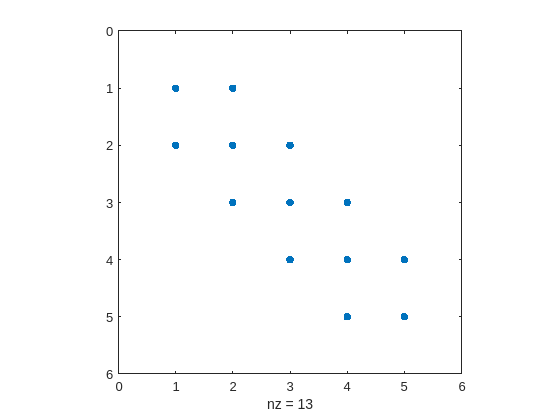

N = 5;
A4 = sparse(N);
A4(1,1)=1;
for i=2:N-1
   A4(i,i-1:i+1) = [-1,2,-1];
end
A4(N,[N-1,N])=[-1,2];
spy(A4)

An alternative, and better, use of `sparse() `is to use triplet format:

sets $A$ to be the $N \times N$ matrix with $a_{I_k, J_k}  = X_k$ 

Example:

I = 1:4

I =      1     2     3     4


J = 2:5

J =      2     3     4     5


X = [-1, 3, -2, 7]

X =     -1     3    -2     7


A5 = sparse(I, J, X, 5, 5)

A5 =    (1,2)       -1
   (2,3)        3
   (3,4)       -2
   (4,5)        7


full(A5)

ans =      0    -1     0     0     0
     0     0     3     0     0
     0     0     0    -2     0
     0     0     0     0     7
     0     0     0     0     0


There are other related functions, including spdiags(), but I rarely find them to more useful than `sparse()`.

## 4. Are sparse matrices faster?

N = 2^8;
A_sparse = sparse(1:N, 1:N, 2) + ...
   sparse(1:N-1, 2:N, -1, N, N) + ...
   sparse(2:N, 1:N-1, -1, N, N);
%full(A_sparse)
%spy(A_sparse)
A_full = full(A_sparse);
b = ones(N,1);
tic;  x = A_full\b; FullTime=toc;
tic;  x = A_sparse\b; SparseTime=toc;
fprintf("N=%4d. Times: Sparse=%8.3gs, Full=%8.3gs (Speedup=%9.3g)\n", ...
   N, SparseTime, FullTime, FullTime/SparseTime);

N=2048. Times: Sparse=0.000118s, Full=   0.102s (Speedup=      861)
